# Phase Portrait for Damped Pendulum

clear; close all; clc

% creates two matrices:
% one for all the x-values on the grid (constant columns)
% one for all the y-values on the grid (constant rows)
y1 = linspace(-2,10,20);
y2 = linspace(-3,3,20);
[X,Y] = meshgrid(y1,y2);

Computing the Vector Field

% Generate two matrices, u and v. 
% U contains the value of y1'(0) at each x and y position
% V contains the value of y2'(0) at each x and y position
U = zeros(size(X));
V = zeros(size(X));
t = 0;

% numel iterates over the 1st column, then 2nd, ...
for i = 1:numel(X)
    y_dot = f(t, [X(i); Y(i)]); % pendulum equation
    U(i) = y_dot(1);
    V(i) = y_dot(2);
end

Plot the Vector Field

quiver(X,Y,U,V,'k');
xlabel('y_1 (radians)')
ylabel('y_2 (rad/s)')
axis tight equal;
title('Vector Field for Damped Pendulum')

Plotting solutions on the vector field for different initial conditions:

 
$$y_1(0)=y_{10}, \\
y_2(0)=y_{20}$$


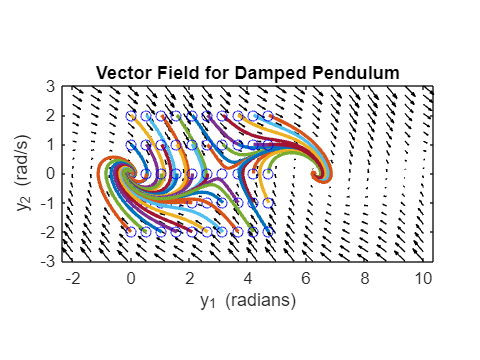

hold on
for y10 = deg2rad(0:30:270)
    for y20 = -2:1:2
        [ts,ys] = ode45(@f,[0 10],[y10; y20]);
        plot(ys(:,1),ys(:,2),'LineWidth',2)
        plot(ys(1,1),ys(1,2),'bo') % starting point
    end
end
hold off

Equation of motion for pendulum with friction:


$$$\dot{y}_1=y_2$
$\dot{y}_2=-ky_2-sin(y_1)$
where $y_1$ is the angle, and $y_2$ is the angular velocity.
$k$ is a linear friction coefficient.$$


function [y_dot] = f(t,y)
k=1;
y_dot(1,:) = y(2);
y_dot(2,:) = -k*y(2)-sin(y(1));
end